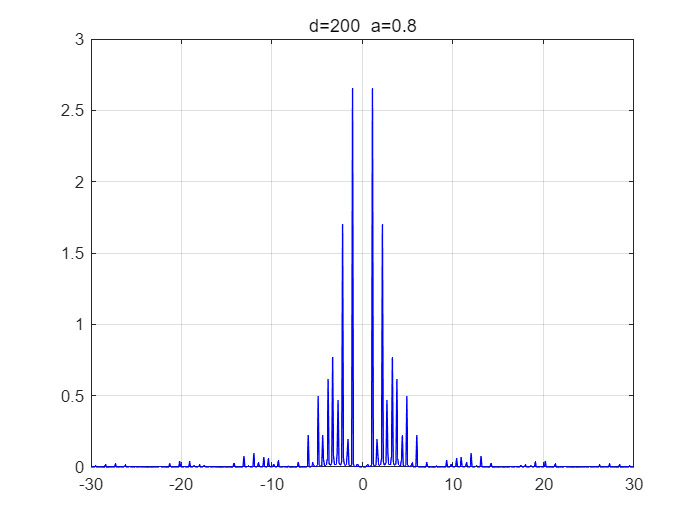

a = 0.8;
d = 200;
omega = -30:0.1:30;
s = size(omega);
for o = 1:s(1,2)
    f = 0;
    for n = -5:5
        f = f + exp(-1i*omega(o)*n*d)*(exp(-1i*omega(o)*a) - 1);
    end
    F(o) = f;
end
F = F.*1i./(2*pi*a*omega);
F = abs(F).^2;
%F = F.^2;
plot(omega, F, 'b-')
grid on
title(['d=',num2str(d),'  ','a=',num2str(a)])